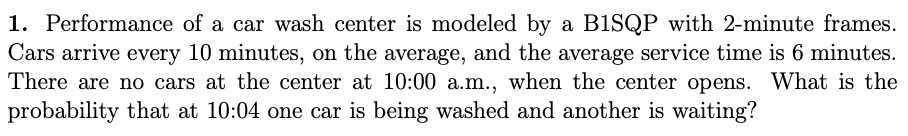

delta = 2; % 2 minutes frames
muA = 10; % cars arrial rate
muS = 6; % average service rate
lambdaA = 1/muA;
lambdaS= 1/muS;
pA = lambdaA * delta;
pS = lambdaS * delta;

% P(one car is being washed and another is waiting) = P(2 cars arrived and one has not finished)
% P(one car has not finished) = 0 because it must take at least 1 frame
P = [
    1-pA       pA                   0;
    (1-pA)*pS  (1-pA)*(1-pS)+pA*pS  pA*(1-pS);
    0          (1-pA)*pS            (1-pA)*(1-pS)+pA*pS;
]

P =                        0.8                       0.2                         0
         0.266666666666667                       0.6         0.133333333333333
                         0         0.266666666666667                       0.6


frames=4/delta;
P_frames = P^frames

P_frames =          0.693333333333333                      0.28        0.0266666666666667
         0.373333333333333         0.448888888888889                      0.16
        0.0711111111111111                      0.32         0.395555555555556


fprintf("P(X_2 = 2 | X_0 = 0) = %g", P_frames(1, 3));

P(X_2 = 2 | X_0 = 0) = 0.0266667

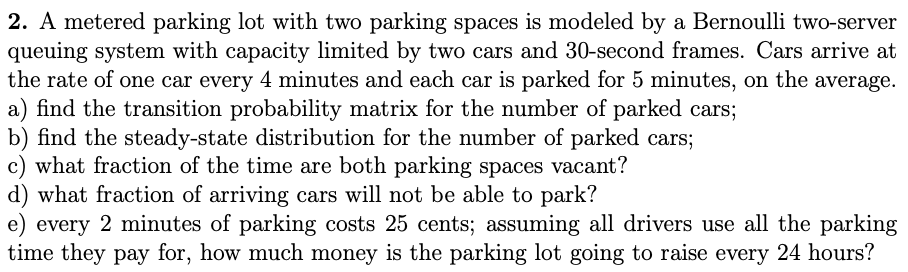

delta = 30/60; % frame duration
muA = 4;
muS = 5;
lambdaA = 1/muA;
lambdaS = 1/muS;

pA = lambdaA * delta;
pS = lambdaS * delta;

% a) Transition Probability Matrix
P = zeros(3, 3);

P = [
    1-pA         pA                          0;
    pS*(1-pA)    (1-pA)*(1-pS)+pA*pS         pA*(1-pS);
    pS^2*(1-pA)  2*pS*(1-pA)*(1-pS)+pS^2*pA  (1-pA)*(1-pS)^2+2*pA*pS*(1-pS)+pA*(1-pS)^2
]

P =                      0.875                     0.125                         0
                    0.0875                       0.8                    0.1125
                   0.00875                   0.15875                    0.8325


% b) Steady-state distribution
A = [P'-eye(3); ones(1,3)];
b = [zeros(3,1); 1];
pi = A\b

pi =          0.308855291576674
         0.413452638074668
         0.277692070348658


% c) Fraction of time both parking spaces are vacant
fprintf("P(X = 0) = pi_0 = %g of time", pi(1));

P(X = 0) = pi_0 = 0.308855 of time

% d) Fraction of arriving cars unable to park
fprintf("P(X = 2) = pi_2 = %g of time", pi(2));

P(X = 2) = pi_2 = 0.413453 of time

% e) Total revenue in 24 hours
E_X = sum(pi .* [0,1,2]');
fprintf("E(x) = %g cars", E_X);

E(x) = 0.968837 cars

revenue = E_X*24*60*0.25/2;
fprintf("Total revenue in 24 hours: %g dollars", revenue);

Total revenue in 24 hours: 174.391 dollars

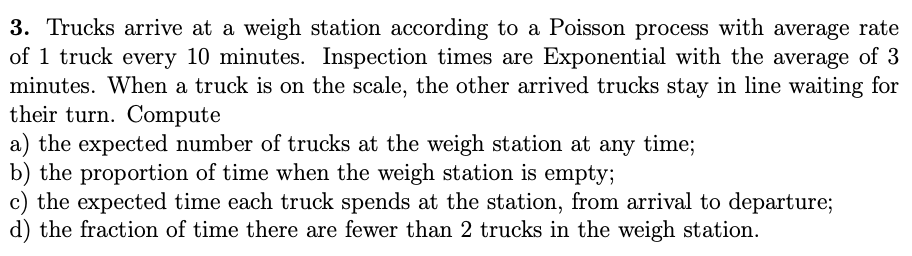

muA = 10;
muS = 3;
lambdaA = 1/muA;
lambdaS = 1/muS;
r = lambdaA/lambdaS;

% a) Expected number of trucks
fprintf("E(X) = %g trucks", r/(1-r))

E(X) = 0.428571 trucks

% b) Proportion of time when the station is empty
fprintf("P(X = 0) = %g of time", 1-r);

P(X = 0) = 0.7 of time

% c) Expected response time
fprintf("E(R) = %g min", muS/(1-r));

E(R) = 4.28571 min

% d) Probability fewer than 2 cars
fprintf("P(X < 2) = P(0) + P(1) = pi_0 + pi_1 = %g of time", (1-r) + r*(1-r));

P(X < 2) = P(0) + P(1) = pi_0 + pi_1 = 0.91 of time

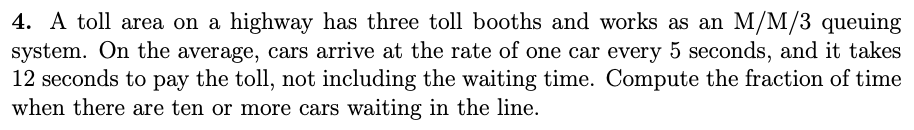

lambdaA = 1/5;
lambdaS = 1/12;
k = 3;
r = lambdaA/lambdaS;

% 10 cars are waiting in line => toll is full (3 cars) => we should compute
% the probability of at least 13 cars at this M/M/3 queue P(X >= 13)
% P(X >= 13) = sum of x=13 to inf of pi_x
% pi_x = r^k/(k!) * pi_0 * (r/k)^(x-k)

pi_0_inv = r^k/(factorial(k)*(1-r/k));
for n = 0:k-1
    pi_0_inv = pi_0_inv + (r^n) / factorial(n);
end
pi_0 = 1/pi_0_inv

pi_0 =         0.0561797752808988


% P(X >= 13) = r^k/(k!) * pi_0 * (r/k)^10 *
%             * (sum from x=0 to inf of (r/k)^x) -- geometric sum
%            = r^k/(k!) * pi_0 * (r/k)^10 * 1/(1-r/3)

P_X_gt_13 = r^k/factorial(k)*pi_0*(r/k)^10/(1-r/3);
fprintf("P(X >= 13) = %g", P_X_gt_13);

P(X >= 13) = 0.0694916

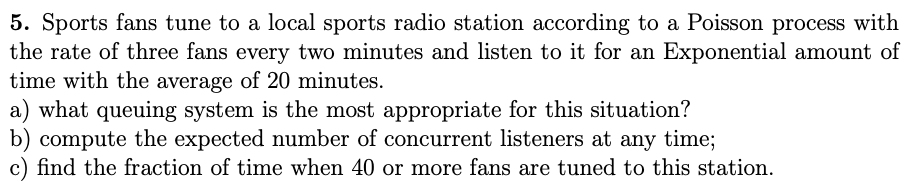

lambdaA = 3/2;
muS = 20;
lambdaS = 1/muS;
r = lambdaA/lambdaS;

% a) The appropiate system is M/M/inf because we have:
%  - a Poisson process of arrivals (Exponential interarrival times)
%  - Exponential service times with infinitely many servers (people
%    listening to radio simultaneously)

% b) Expected number of concurrent listeners
fprintf("E(X) = %g", r);

E(X) = 30

% c) Fraction of time where there are more than 40 listeners
% P(X >= 40) = 1 - P(X < 40) = 1 - P(X <= 39)
fprintf("P(X >= 40) = %g", 1-poisscdf(39,r));

P(X >= 40) = 0.046253

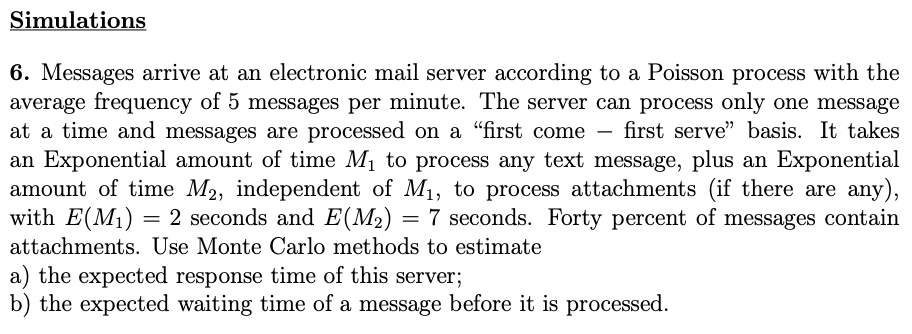

t = cputime;
lamA = 5/60;
lamM1 = 1/2; % text
lamM2 = 1/7; % attachments
p = 0.4; % prop email with attach
N = 1e6; % input: size of MC study
arrival = zeros(1,N); % times then services arrive
start = zeros(1,N); 
finish = zeros(1,N);
T = 0; % arrival time of a new job
A = 0; % time when the server becomes available
for j = 1:N 
    T = T - 1/lamA * log(rand); % arrival time of the jth job
    S = -1/lamM1 * log(rand) - (rand<p)*1/lamM2 * log(rand); % service time of the jth job
    arrival(j) = T;
    start(j) =  max(A,T);
    finish(j) = start(j)+S;
    A = finish(j); % when the server beomes available to take the (j+1)st job
end
el_time = cputime-t

el_time =          0.230000000000018


expected_respone_time = mean(finish-arrival) % E(R) ~= 8.8s

expected_respone_time =            8.9015644835517


expected_waiting_time = mean(start-arrival) % E(W) ~= 4s

expected_waiting_time =           4.09286949049274


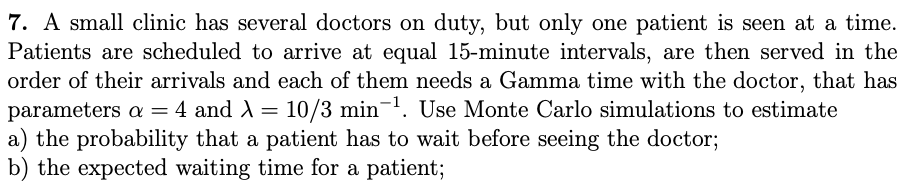

tcpu = cputime;
alpha = 4; lambda = 10/3;
t = 15;
N = 1e6;

arrival = 0:t:(N-1)*t; % arrival times 0,t,2t,...
start = zeros(1,N); % times when srvice starts
finish = zeros(1,N);
A=0; % departure times

for j=1:N
    start(j) = max(A, arrival(j));
    S = -lambda*sum(log(rand(alpha, 1)));
    finish(j) = start(j)+S;
    A = finish(j);
end

el_time = cputime-tcpu

el_time =          0.360000000000014


probability_has_to_wait = mean(start>arrival) % E(W>0) ~= 0.66

probability_has_to_wait =                   0.660614


expected_waiting_time = mean(start-arrival) % E(W) ~= 10-11 minutes

expected_waiting_time =            10.600765185701
